8.  Compute and plot the phase response using the functions freqz, angle, phasez, unwrap, and phase delay for the following systems:

clc;clear;close all;
om=linspace(-pi, pi, 360);

(a) $y[n]=x[n-15]$

-sol-

$H(z)=z^{-15}$ and $H(e^{j\omega})=e^{-15j\omega}$. $\angle H(e^{j\omega})=-15\omega$

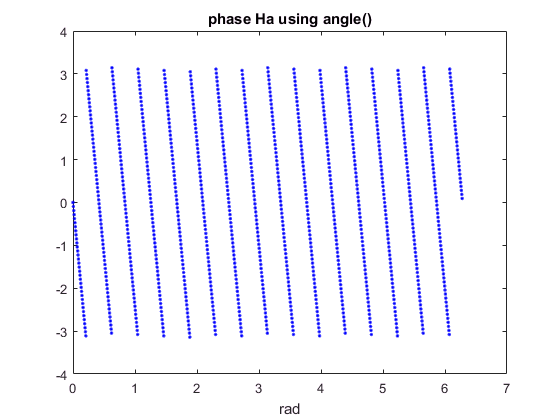

b=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
a=[1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

% Find the frequency response at 360 points spanning the complete unit circle.
[Ha, w]=freqz(b,a,'whole',1000); 

phase_Ha1 = angle(Ha);
plot(w, phase_Ha1, '.b')
title('phase Ha using angle()')
xlabel('rad');

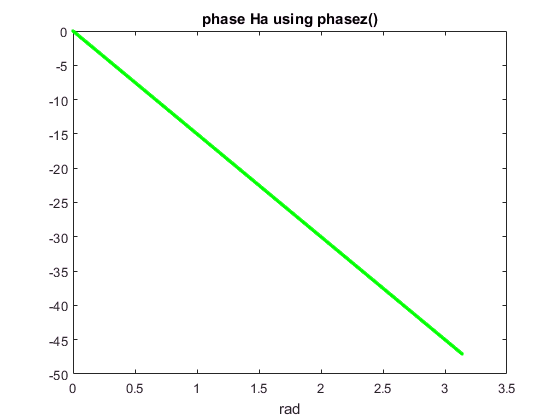


[phi, w] = phasez(b,a,1000);
plot(w, phi, '.g')
title('phase Ha using phasez()')
xlabel('rad');

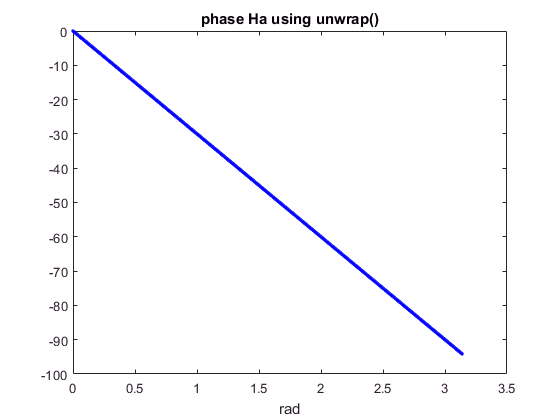


phase_Ha2 = unwrap(phase_Ha1);
plot(w, phase_Ha2, '.b')
title('phase Ha using unwrap()')
xlabel('rad');

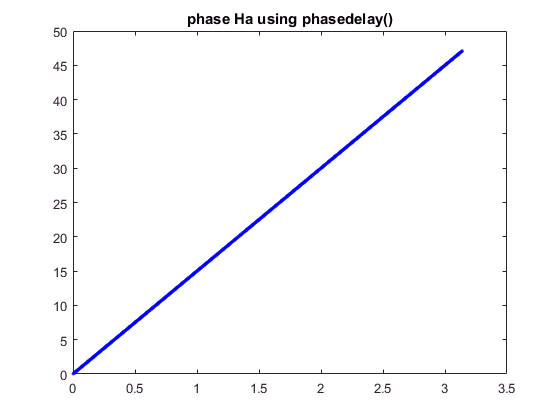


[phi2,w] = phasedelay(b,a,1000);
plot(w, phi2.*w, '.b')
title('phase Ha using phasedelay()')

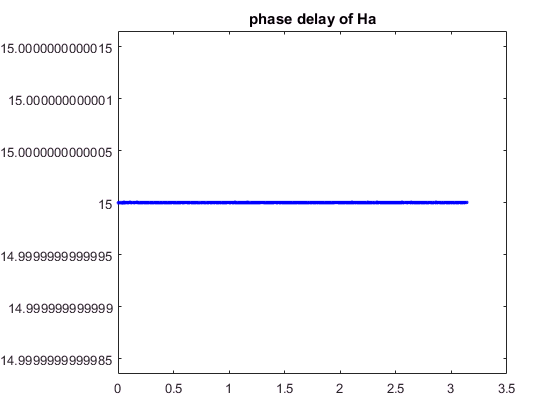


plot(w, phi2, '.b')
title('phase delay of Ha')

(b) $H(z)=\frac{1+1.655z^{-1}+1.655z^{-2}+z^{-3}}{1-1.57z^{-1}+1.264z^{-2}-0.4z^{-3}}$

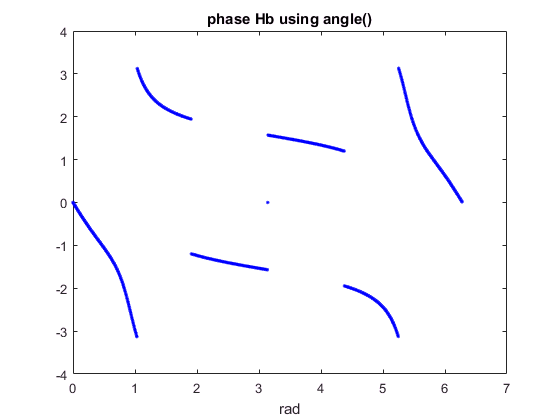

b=[1 1.655 1.655 1];
a=[1 -1.57 1.264 -0.4];

% Find the frequency response at 360 points spanning the complete unit circle.
[Hb, w]=freqz(b,a,'whole',1000); 

phase_Hb1 = angle(Hb);
plot(w, phase_Hb1, '.b')
title('phase Hb using angle()')
xlabel('rad');

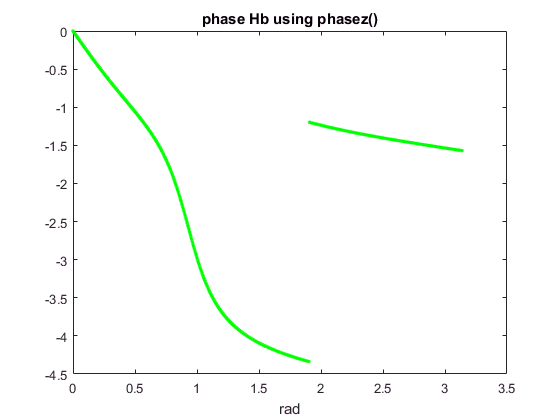


[phi3, w] = phasez(b,a,1000);
plot(w, phi3, '.g')
title('phase Hb using phasez()')
xlabel('rad');

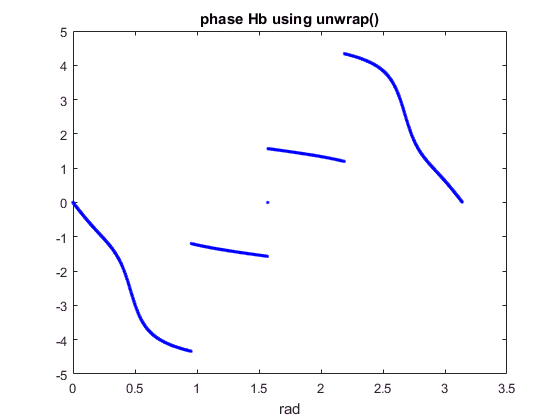


phase_Hb2 = unwrap(phase_Hb1);
plot(w, phase_Hb2, '.b')
title('phase Hb using unwrap()')
xlabel('rad');

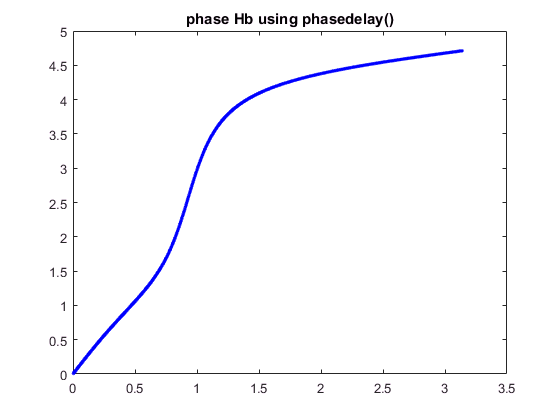


[phi4,w] = phasedelay(b,a,1000);
plot(w, phi4.*w, '.b')
title('phase Hb using phasedelay()')

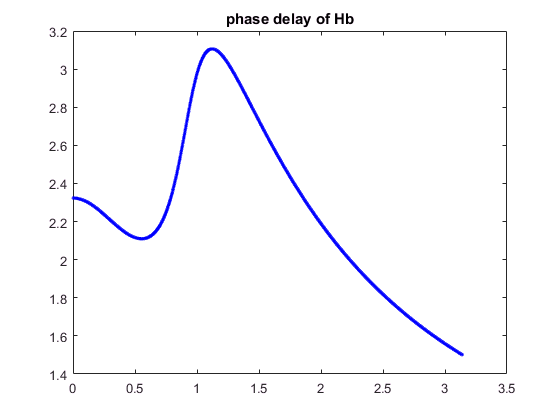


plot(w, phi4, '.b')
title('phase delay of Hb')

9. According to problem 2 in paper assignment, plot magnitude response, phase response and group-delay response for each of the systems. 

(a)

clc;clear;close all;
om=linspace(-pi, pi, 360);

ha=[1 -2 3 -4 0 4 -3 2 -1];

Ha=freqz(ha, 1, om);
Ha_mag = abs(Ha);
Ha_phase = angle(Ha);

figure(11)
subplot(2,1,1)
plot(om, Ha_mag, '.b')
title('|Ha| in problem 2(a)')
subplot(2,1,2)
plot(om, Ha_phase, '.g')
title('angle(Ha) in problem 2(a)')

(b) 

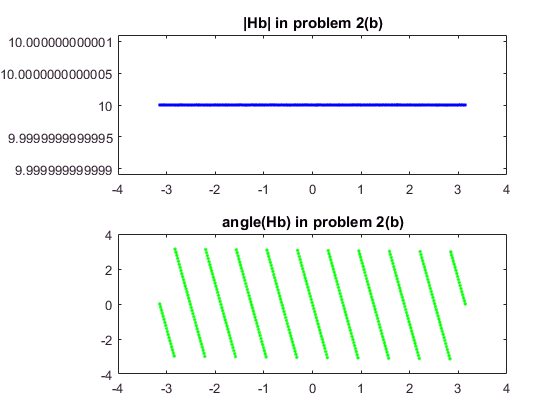

hb=[0 0 0 0 0 0 0 0 0 0 10];

Hb=freqz(hb, 1, om);
Hb_mag = abs(Hb);
Hb_phase = angle(Hb);

figure(11)
subplot(2,1,1)
plot(om, Hb_mag, '.b')
title('|Hb| in problem 2(b)')
subplot(2,1,2)
plot(om, Hb_phase, '.g')
title('angle(Hb) in problem 2(b)')

10.  MATLAB provides a function called polystab that stabilizes the given polynomial with respect to the unit circle, that is, it reﬂects those roots which are outside the unit-circle into those that are inside the unit circle but with the same angle. 

Using this function, convert the following systems into minimum-phase and maximum-phase systems. Verify your answers using a polezero plot for each system(plot minimum-phase and maximum-phase systems for each question). 

(a) $H(z)=\frac{z^2+2z+0.75}{z^2-0.5z}$

-sol-


$$H(z)=\frac{1+0.5z^{-1}}{1-0.5z^{-1}}(1+\frac{3}{2}z^{-1})\cdot\frac{z^{-1}+\frac{3}{2}}{1+\frac{3}{2}z^{-1}}=H_{\text{min}}(z)H_{\text{ap}}(z)$$



$$H_{\text{min}}(z)=\frac{(z+\frac{1}{2})(z+\frac{3}{2})}{z-\frac{1}{2}}$$



$$H_{\text{ap}}(z)=\frac{1+\frac{3}{2}z}{\frac{3}{2}+z}$$


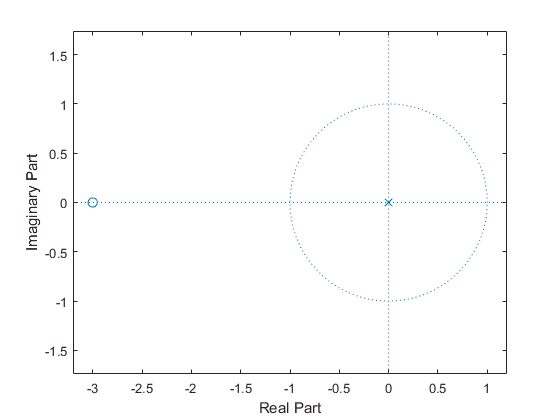

clc;clear;close all;

b=[0.75 2 1];
a=[-0.5 1];

z=[-0.5 -1.5];
p=[0.5];
zplane(z,p) %第一張圖

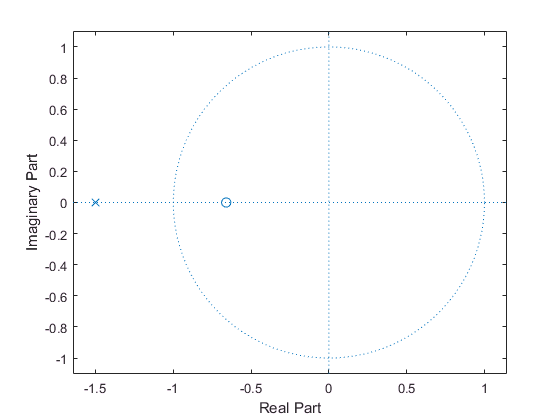


z1=[-0.66];
p1=[-1.5];
zplane(z1,p1) %第二張圖

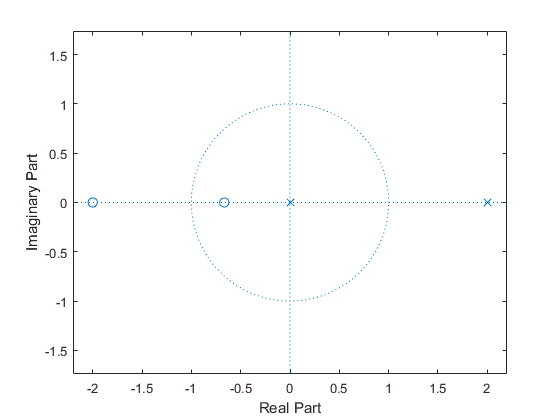


zp=polystab(b);
zplane(b,a) %第三章圖=把第一章和第二張圖重疊

(b) $H(z)=\frac{1-2.4142z^{-1}+2.4142z^{-2}-z^{-3}}{1-1.8z^{-1}+1.62z^{-2}+0.729z^{-3}}$


$$H(z)=\frac{z^3-2.4142z^2+2.4142z-1}{z^3-1.8z^2+1.62z+0.729}$$


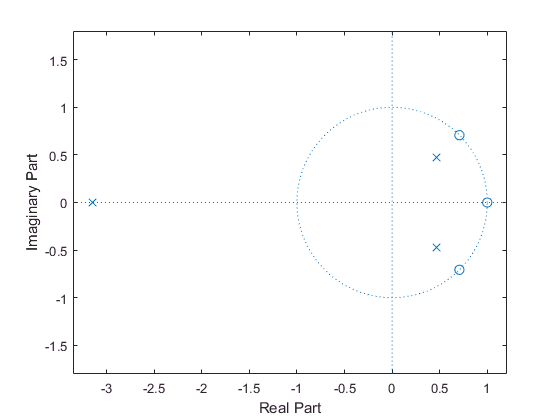

b=[-1 2.4142 -2.4142 1];
a=[0.729 1.62 -1.8 1];

zp2=polystab(b);
zplane(b,a)

zplane(zp2,a)

% It looks same.

z2=roots(b) % It's on unit circle, so two plots are same

z2 =    1.0000 + 0.0000i
   0.7071 + 0.7071i
   0.7071 - 0.7071i


p2=roots(a)

p2 =   -3.1458 + 0.0000i
   0.4618 + 0.4721i
   0.4618 - 0.4721i


11.  Signal $x_c(t) = 5\cos(200\pi t + \pi6 )+4\sin(300\pi t)$ is sampled at a rate of $F_s = 1$ kHz to obtain the discrete-time signal $x[n]$.  

(a) Determine the spectrum $X(e^{j\omega})$ of $x[n]$ and plot its magnitude as a function of $\omega$ in $\text{rad/sample}$ and as a function of $F$ in Hz. Explain whether the original signal $x_c(t)$ can be recovered from $x[n]$.

-sol-

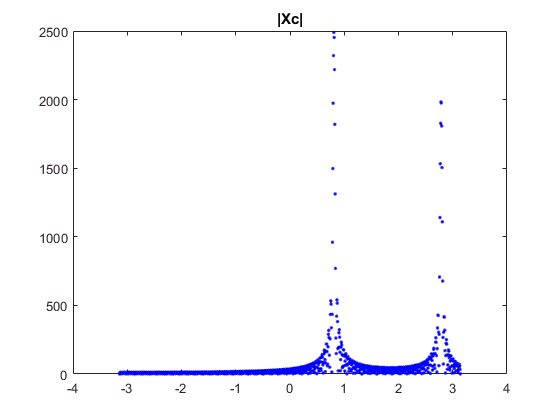

clc;clear;close all;

Fs = 1000;
t = 0:1/Fs:1-1/Fs;
xc = 5*cos(200*pi*t + 6*pi) + 4*sin(300*pi*t);
Xc=freqz(xc, 1, t);
Xc_mag = abs(Xc);

figure(12)
om=linspace(-pi, pi, 1000);
plot(om, Xc_mag, '.b')
title('|Xc|')

(b) Repeat part (a) for $F_s = 500$ Hz. 

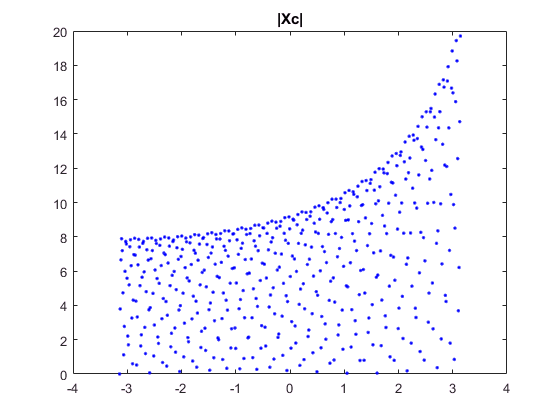

Fs = 500;
t = 0:1/Fs:1-1/Fs;
xc = 5*cos(200*pi*t + 6*pi) + 4*sin(300*pi*t);
Xc=freqz(xc, 1, t);
Xc_mag = abs(Xc);

figure(12)
om=linspace(-pi, pi, 500);
plot(om, Xc_mag, '.b')
title('|Xc|')

(c) Repeat part (a) for $Fs = 100 $ Hz.

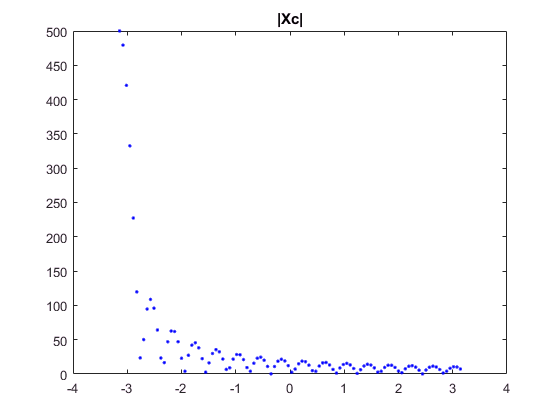

Fs = 100;
t = 0:1/Fs:1-1/Fs;
xc = 5*cos(200*pi*t + 6*pi) + 4*sin(300*pi*t);
Xc=freqz(xc, 1, t);
Xc_mag = abs(Xc);

figure(12)
om=linspace(-pi, pi, 100);
plot(om, Xc_mag, '.b')
title('|Xc|')

(d) Comment on your results. 

-sol-

Beside using sampling theorem, one can reveals that the signals can't be reconstructed if we can't tell the difference of two different frequency component in the spectrum. Hence, (c) can't be recovered.